# Pdf and Cdf of Gamma RV

Note: this script reproduces the figure of the Gamma RV in Section 2.2.5 of **Statistics for Chemical Engineers**, with realizations of Gamma(1,1) and Gamma(2,1). Victor Z UW-Madison, 2020 compare gamma RVs

clc; clear all; close all hidden;

## Parameters

parameters

 beta=[1,1,0.5,0.5];
alpha=[1,2,1,2];
w=[0.5,1,1.5,2];
x=linspace(0,4,1000);

## Realizations

generate realizations

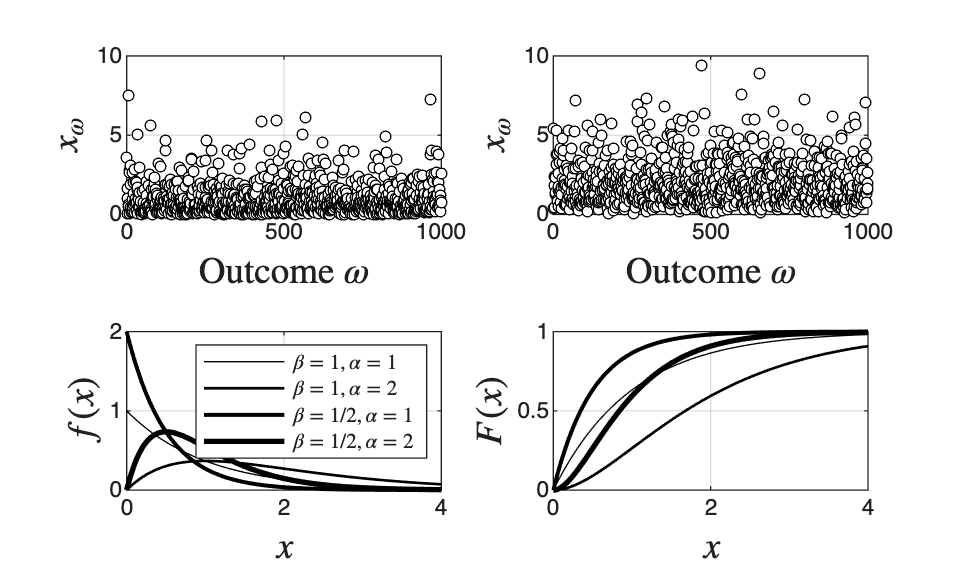

S=1000;
rng(0);
figure(1)
subplot(2,2,1)
X = gamrnd(1,1,S,1);
plot(X,'blacko','MarkerFaceColor','w','MarkerSize',4)
xlabel('Outcome $\omega$','Interpreter','latex','FontSize',14)
ylabel('$x_\omega$','Interpreter','latex','FontSize',14)
grid on
axis([0,1000,0 10])
subplot(2,2,2)
X = gamrnd(2,1,S,1);
plot(X,'blacko','MarkerFaceColor','w','MarkerSize',4)
xlabel('Outcome $\omega$','Interpreter','latex','FontSize',14)
ylabel('$x_\omega$','Interpreter','latex','FontSize',14)
grid on
axis([0,1000,0 10])

figure(1)
subplot(2,2,3)
for k=1:length(beta)
plot(x,gampdf(x,alpha(k),beta(k)),'black','LineWidth',w(k))
hold on
end
grid on
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$f(x)$','Interpreter','latex','FontSize',14)
lgd=legend('$\beta=1,\alpha=1$','$\beta=1,\alpha=2$','$\beta=1/2,\alpha=1$','$\beta=1/2,\alpha=2$','Interpreter','latex','location','northeast');
lgd.FontSize = 8;

subplot(2,2,4)
for k=1:length(beta)
plot(x,gamcdf(x,alpha(k),beta(k)),'black','LineWidth',w(k))
hold on
end
grid on
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$F(x)$','Interpreter','latex','FontSize',14)
title('')
print -depsc ch2_comparegammas.eps

## Note

The Gamma RV generalizes the exponential RV (alpha = 1): it models the waiting time until the alpha-th event.